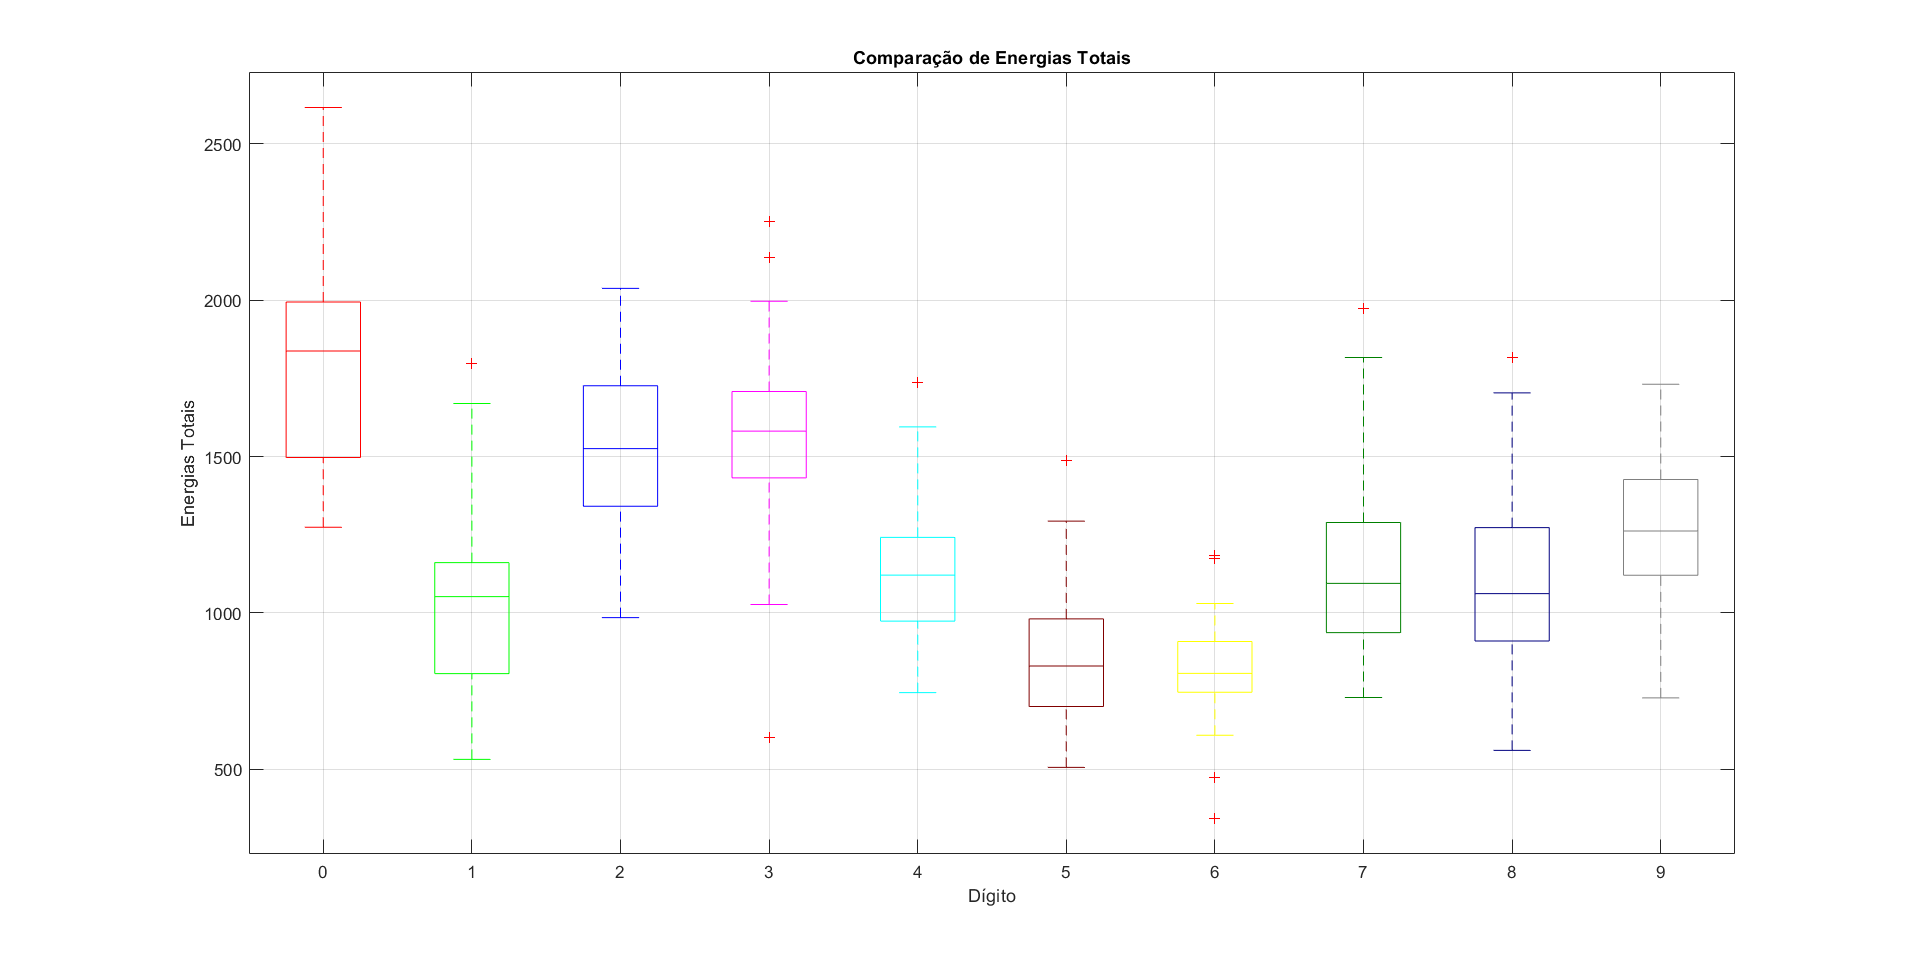

    diretorio = 'C:\Users\jvaz1\Downloads\data\49';
    %rng é usado para a seed() que será usado para mostrar os graficos iniciais
    %de forma aleatoria
    rng(42);
    %Array com as cores utilizadas nos gráficos
    cores = [...
            1 0 0; % Vermelho -0
            0 1 0; % Verde-1
            0 0 1; % Azul-2
            1 0 1; % Magenta-3
            0 1 1; % Azul-Ciano-4
            0.5 0 0; % Castanho-5
            1 1 0; % Amarelo-6
            0 0.5 0; % Verde escuro-7
            0 0 0.5; % Azul escuro-8
            0.5 0.5 0.5; % Cinzento-9
        ];
    % META 1______________________________
    %Chamada de todas as funçoes necessarias para a meta 1
    %graficos_iniciais(diretorio);
    matriz=processamento(diretorio);
    mostrar_energias=energia_total(matriz,cores);

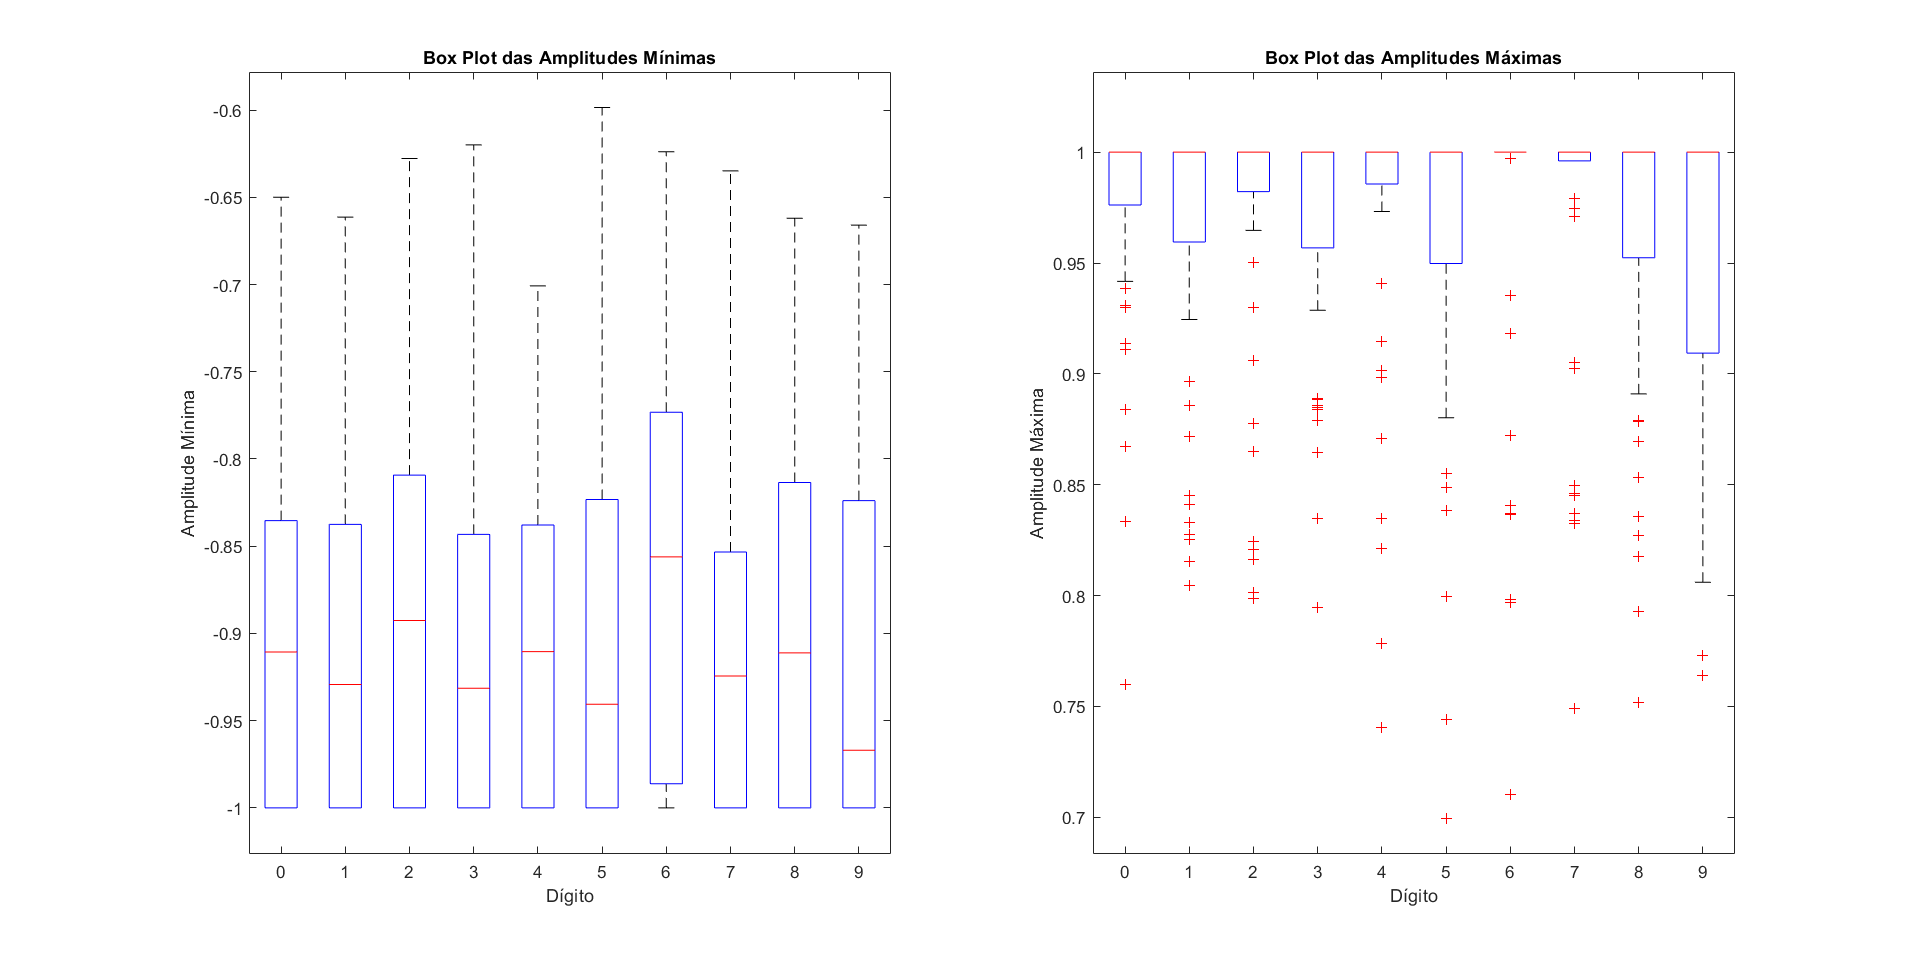

    [amp_min,amp_max]=amplitudeMin_Max(matriz,cores);

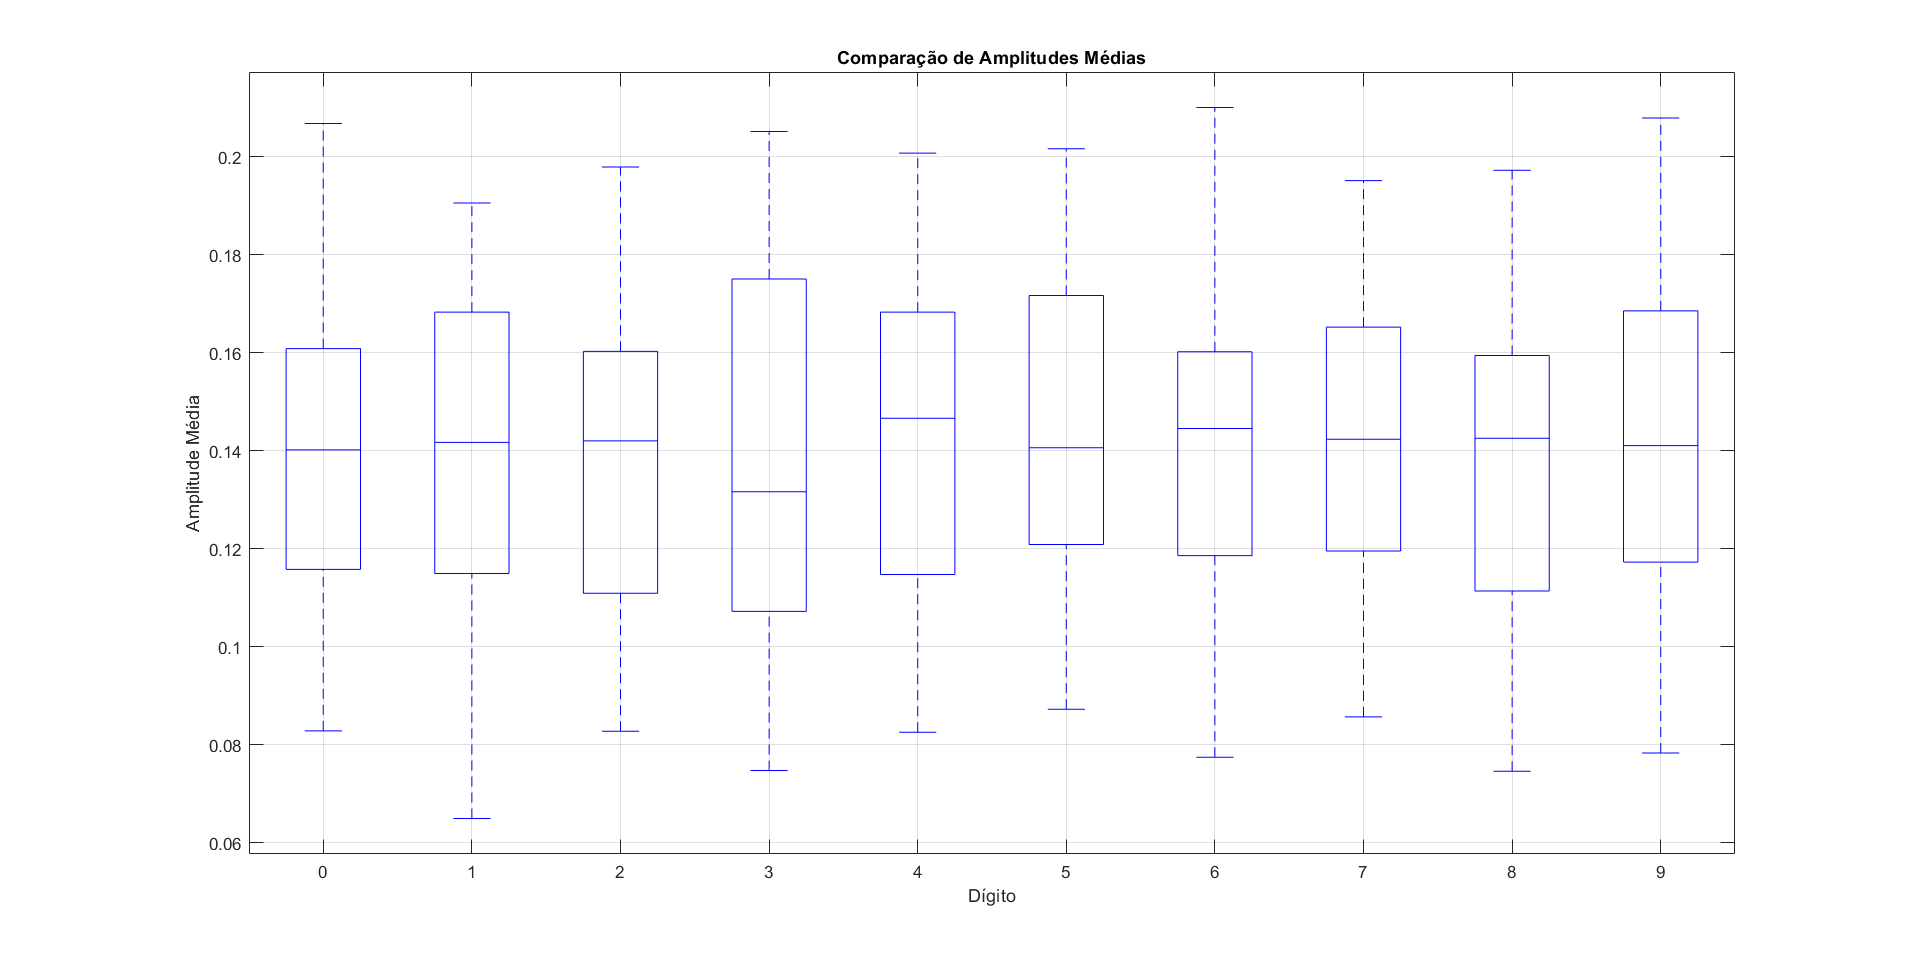

    amp_med=AmplitudeMedia(matriz,cores);

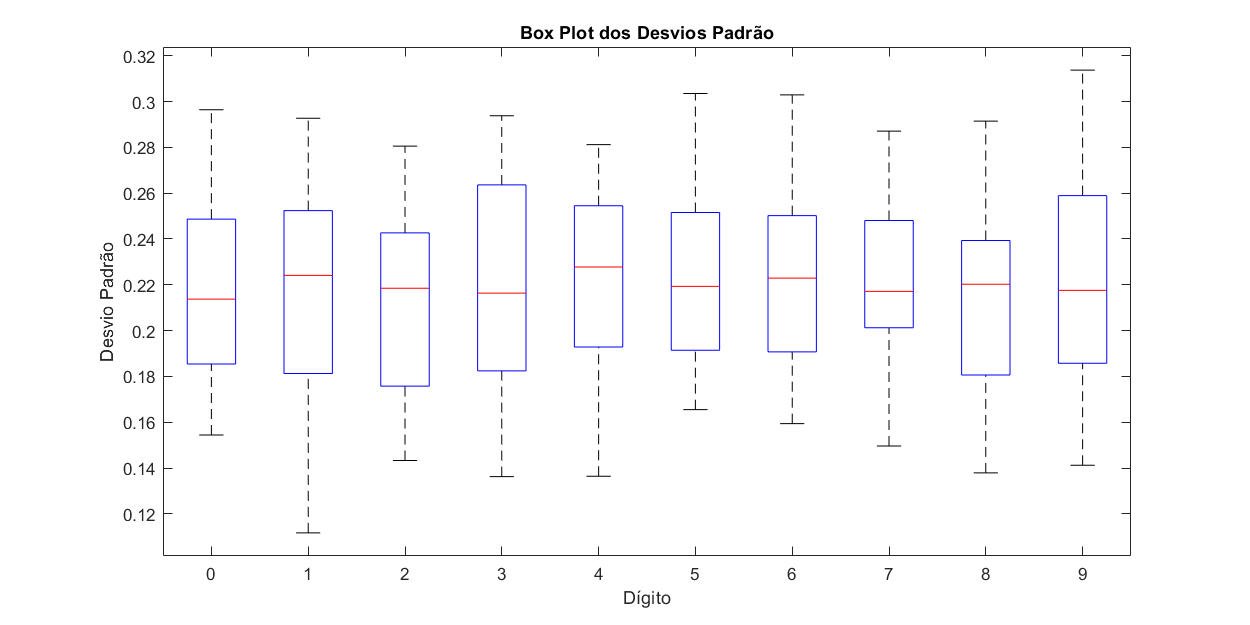

    desv_padrao=DesvioPadrao(matriz,cores);

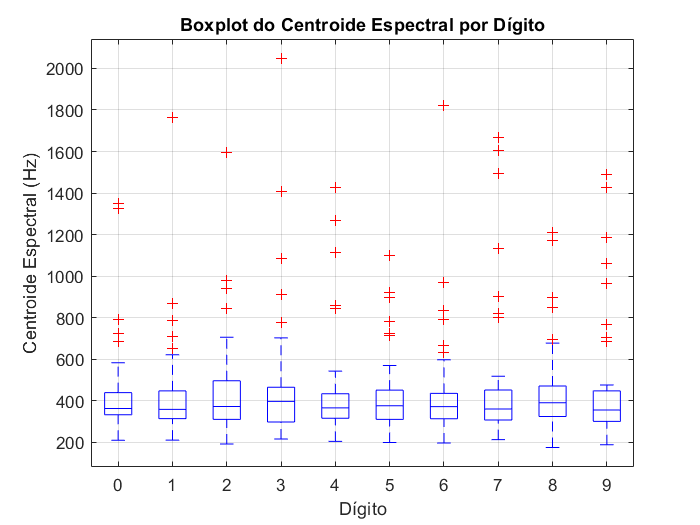

     %energia_intervalor=EnergiaTotalPorIntervalos(matriz,cores);
     %tres_caracteristicas(desv_padrao,mostrar_energias,amp_min,cores);
    % META 2______________________________
     %quartis(matriz,48000,1024);
     %entropias_numero=entropia_espectral(matriz);
     CentroideEspectral(matriz);

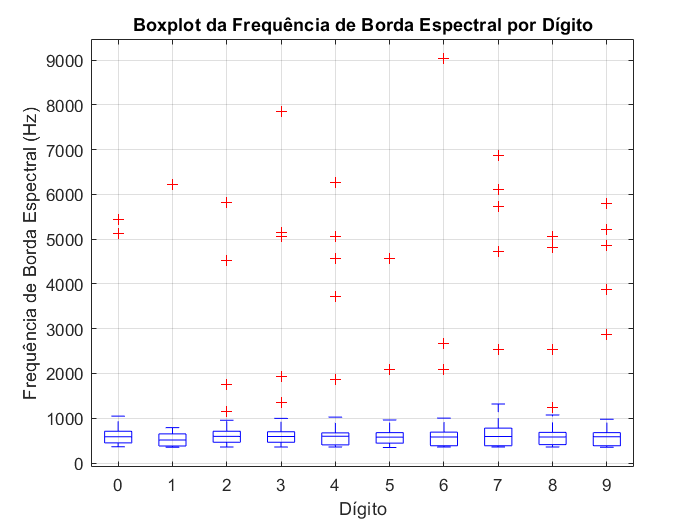

     [maximo_espectral,indice_max]=MaximoEspectral(matriz);
     freq_edge=FrequenciaEdgeEspectral(matriz,0.9);

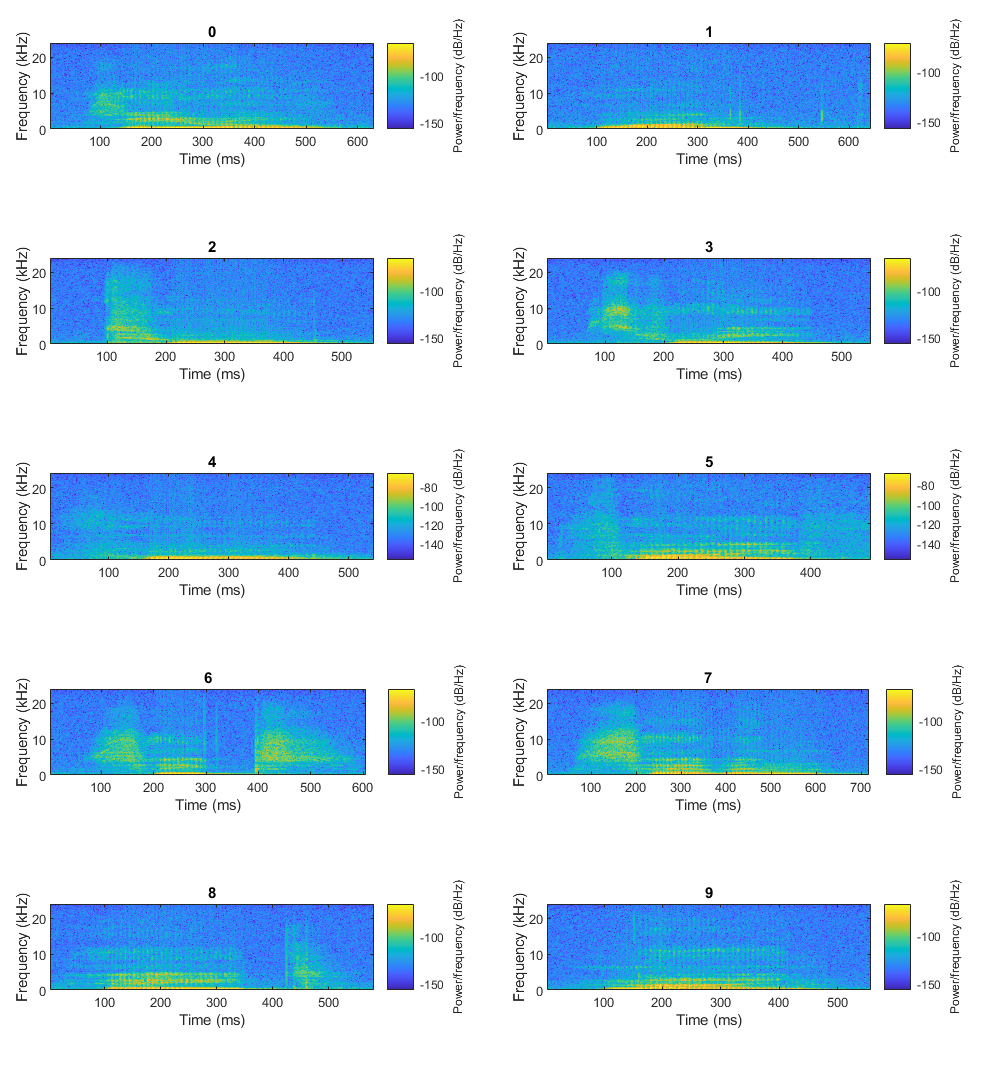

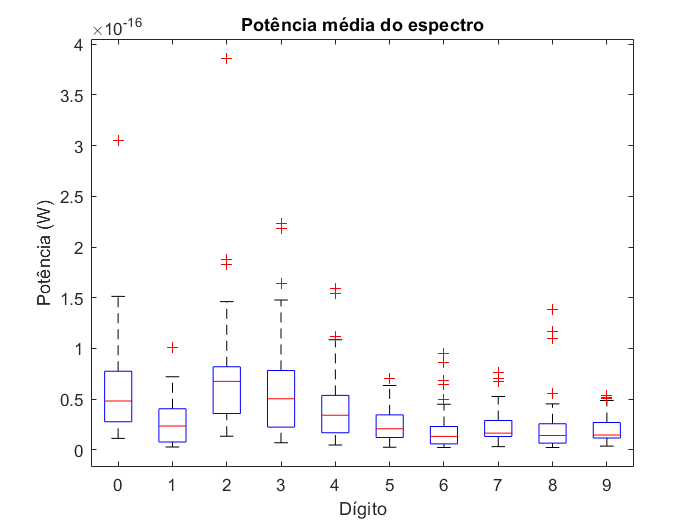

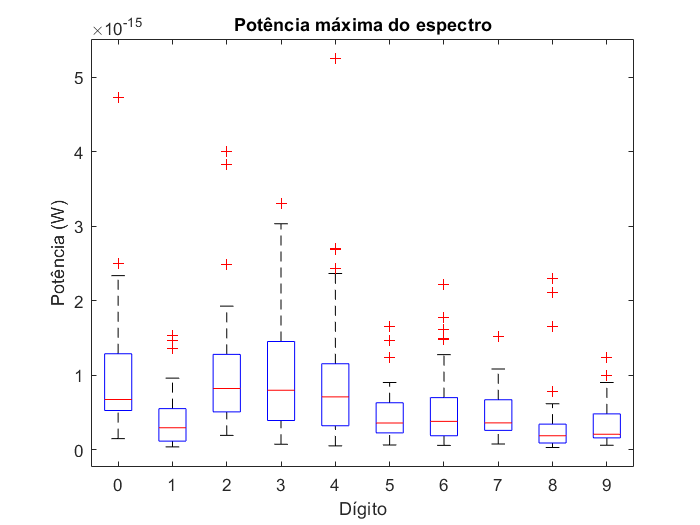

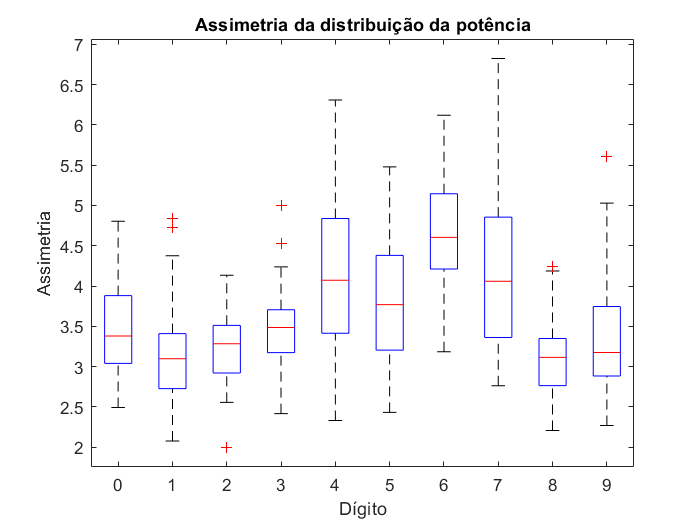

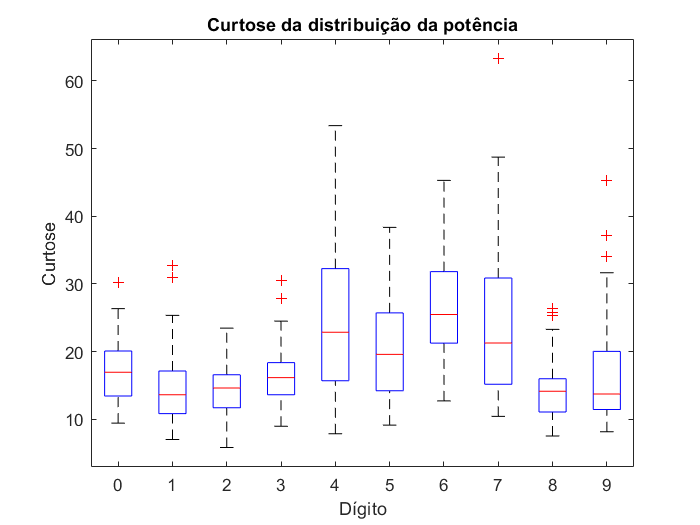

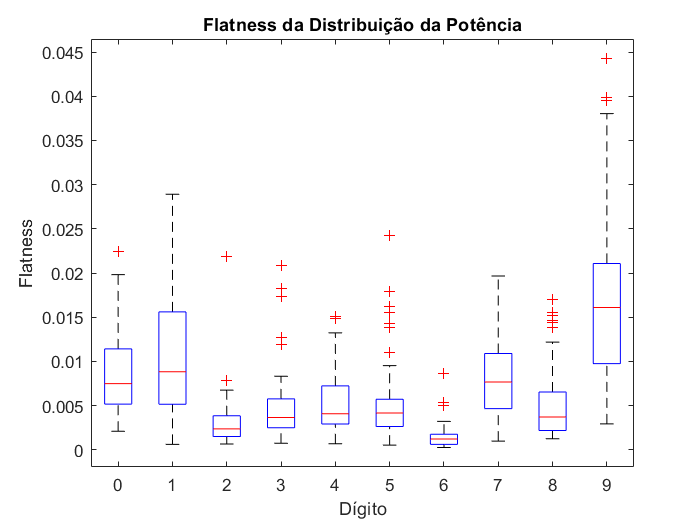

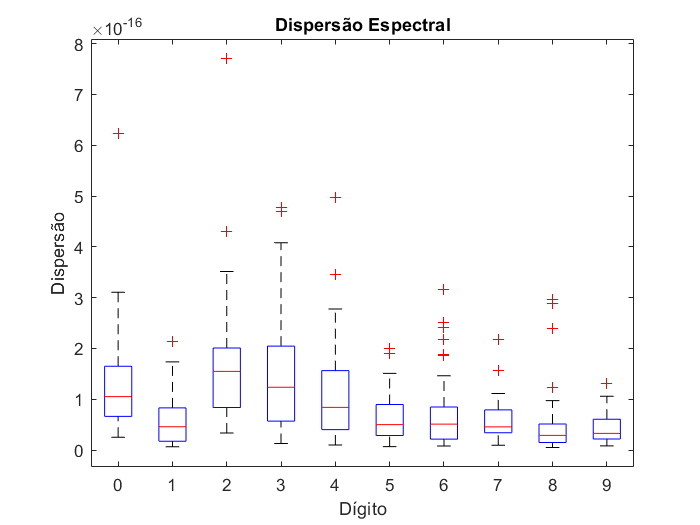

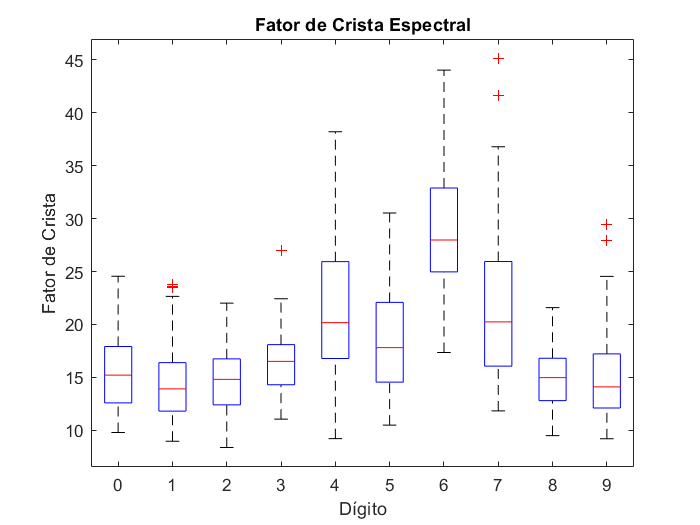

     %tres_caracteristicas_2(entropias_numero,freq_edge,maximo_espectral,cores);
    %META 3______________________________________
    [power_med,power_max, asymmetry, curtose, flatness, spectal_spread, spectral_entropy,spectral_crest_factor,power_range, power_std]=meta3();

    %META 4_______________
    meta_final(spectral_entropy,flatness);

Contagem das ocorrências para cada dígito:


ans = 64

ans = 34

ans = 0

ans = 0

ans = 0

ans = 0

ans = 98

ans = 0

ans = 0

ans = 56.0000

    %Função responsável por mostrar os gráficos iniciais 

    function graficos_iniciais(diretorio)
        indices_a_mostrar=zeros(1,10);
        arquivos = dir(fullfile(diretorio, '*.wav'));
        for i = 1:numel(arquivos)
        %Selecionar aleatoriamente a cada 50 
           if mod(i, 50) == 1
            indice_aleatorio = randi([0, 49]) + i - 1;
            conjunto = ceil(i / 50);
            %Verifica se ainda nao mostrou
            while ismember(indice_aleatorio, indices_a_mostrar)
                indice_aleatorio = randi([0, 49]) + i - 1;
            end

            indices_a_mostrar(conjunto) = indice_aleatorio;

            nome_arquivo = fullfile(diretorio, arquivos(indice_aleatorio).name);

            [audio, taxa_amostragem] = audioread(nome_arquivo);
            figure;
            % Ajustando o tempo para iniciar de 0
            tempo = (0:length(audio)-1) / taxa_amostragem;
            plot(tempo, audio);
            xlabel('Tempo (s)');
            ylabel('Amplitude');
            title(['Dígito ', num2str(conjunto-1), ': ', arquivos(indice_aleatorio).name], 'Interpreter', 'none');
        end
        end
    end

    %Função responsável por retirar o silêncio inicial dos audios
        function sinal_audio = retira_silencio(sinal_audio)
            %Defenição do limiar
            limiar_amplitude = 0.001; 
            indice_inicio = find(abs(sinal_audio) > limiar_amplitude, 1, 'first');
            audio_sem_silencio = sinal_audio(indice_inicio:end);
            sinal_audio = audio_sem_silencio;
            end

    %Função responsável por normalizar os audios(amplitude entre 1 e -1)
    function audio_normalizado = normalizar_amplitude(audio)
        max_amp = max(abs(audio));
        audio_normalizado = audio / max_amp;
    end

    %Funnção responsável por igualar a duração dos audios
    function audio = ajustar_duracao(audio, taxa_amostragem)
        duracao_maxima = max(length(audio)) / taxa_amostragem;
        duracao_atual = length(audio) / taxa_amostragem;
        if duracao_atual < duracao_maxima
            audio = [audio; zeros((duracao_maxima - duracao_atual) * taxa_amostragem, 1)];
        elseif duracao_atual > duracao_maxima
            audio = audio(1:duracao_maxima * taxa_amostragem);
        end
    end

    %Função que irá processar os audios e introduzi-los numa matriz
    function matriz = processamento(caminho_pasta)
        matriz = struct('tempo_audio', {}, 'sinal_audio', {});
        for i = 1:10
             arquivos_audio = dir(fullfile(caminho_pasta, [num2str(i-1), '*.wav']));
             for j = 1:50
                 [audio, taxa_amostragem] = audioread(fullfile(caminho_pasta, arquivos_audio(j).name));
                 %Chamada das funções mencionadas acima
                 audio = retira_silencio(audio);
                 audio = normalizar_amplitude(audio);
                 audio = ajustar_duracao(audio, taxa_amostragem);
                 tempo_audio = linspace(0, length(audio)/taxa_amostragem, length(audio));
                 %Introdução dos audios e tempos numa matriz
                 matriz(j+(50*(i-1)),1).sinal_audio = audio; 
                 matriz(j+(50*(i-1)),1).tempo_audio = tempo_audio; 
             end
        end
    end

    %Função que nos permite comparar a energia total através de um gráfico
    function energiasTotais = energia_total(matriz, cores)
        numeros = 0:9;
        energiasTotais = zeros(10, 50);

        % Calcula a energia total para cada sinal de áudio
        for i = 1:10
            for j = 1:50
                totalEnergia = sum(matriz(j + (50 * (i - 1))).sinal_audio .^ 2);
                energiasTotais(i, j) = totalEnergia;
            end
        end

        % Criação do boxplot para as energias totais
        figure('Position', [100, 100, 2000, 1000]);
        boxplot(energiasTotais', 'Colors', cores(1:size(cores, 1), :));

        % Definindo labels dos eixos e título
        xlabel('Dígito');
        ylabel('Energias Totais');
        title('Comparação de Energias Totais');
        xticklabels(numeros);

       
        grid on;
    end


    %Função que mostra as amplitudes médias dos sinais 
    function amplitudesMedias = AmplitudeMedia(matriz, cores)
        numeros = 0:9;
        % Matriz 10x50 que armazenará os dados
        amplitudesMedias = zeros(10, 50);     

        % Calcula a amplitude média para cada sinal de áudio
        for i = 1:10
            for j = 1:50
                % Uso da função mean
                ampMedia = mean(abs(matriz(j + (50 * (i - 1)), 1).sinal_audio));
                amplitudesMedias(i, j) = ampMedia;
            end
        end

        % Criação do boxplot para as amplitudes médias
        figure('Position', [100, 100, 2000, 1000]);

        % Transforma a matriz em um vetor coluna
        data = amplitudesMedias(:);

        % Cria um vetor de grupos correspondente aos dígitos de 0 a 9
        groups = repelem(0:9, 50)';

        boxplot(data, groups, 'Colors', 'b');

        % Definindo labels dos eixos e título
        xlabel('Dígito');
        ylabel('Amplitude Média');
        title('Comparação de Amplitudes Médias');

        % Define os rótulos do eixo x para mostrar os dígitos de 0 a 9
        set(gca, 'XTickLabel', 0:9);

        % Exibir grade para melhor visualização
        grid on;
    end


    %Função que nos permite compararar a amplitude mínima e máxima dos sinais
    function [amplitudeMin, amplitudeMax] = amplitudeMin_Max(matriz, cores)
        % Matrizes 10x50 que armazenarão os dados
        amplitudeMin = zeros(10, 50);
        amplitudeMax = zeros(10, 50);
        numeros = 0:9;

        % Coletando todos os valores de amplitude mínima e máxima
        for i = 1:10
            for j = 1:50
                idx = j + (50 * (i - 1));
                amplitudeMin(i, j) = min(matriz(idx).sinal_audio);
                amplitudeMax(i, j) = max(matriz(idx).sinal_audio);
            end
        end

        
        amplitudeMinAll = amplitudeMin(:);
        amplitudeMaxAll = amplitudeMax(:);
        digits = repelem(numeros, 50);

        
        figure('Position', [100, 100, 2000, 1000]);

        subplot(1, 2, 1);
        boxplot(amplitudeMinAll, digits);
        xlabel('Dígito');
        ylabel('Amplitude Mínima');
        title('Box Plot das Amplitudes Mínimas');
        set(gca, 'XTickLabel', numeros);

        subplot(1, 2, 2);
        boxplot(amplitudeMaxAll, digits);
        xlabel('Dígito');
        ylabel('Amplitude Máxima');
        title('Box Plot das Amplitudes Máximas');
        set(gca, 'XTickLabel', numeros);
    end


    %Função responsável por mostrar o desvio padrão
    function desviosPadrao = DesvioPadrao(matriz, cores)
        % Matriz 10x50 que armazenará os dados
        desviosPadrao = zeros(10, 50);
        numeros = 0:9;

        
        for i = 1:10
            for j = 1:50
                idx = j + (50 * (i - 1));
                desviosPadrao(i, j) = std(matriz(idx).sinal_audio);
            end
        end

        
        desviosPadraoAll = desviosPadrao(:);
        digits = repelem(numeros, 50);

        
        figure('Position', [100, 100, 1000, 500]);
        boxplot(desviosPadraoAll, digits);
        xlabel('Dígito');
        ylabel('Desvio Padrão');
        title('Box Plot dos Desvios Padrão');
        set(gca, 'XTickLabel', numeros);
    end


    %Função que mostra a energia en«m diferentes intervalos de tempo do sinal
    function energiasPorIntervalo = EnergiaTotalPorIntervalos(matriz, cores)
        intervalos = linspace(0, 1, 11);
        numeros = 0:9;
        energiasPorIntervalo = zeros(10, 10, 50);   

        % Calcular energias por intervalo
        for i = 1:10
            a = 0;
            b = 0.1;
            for j = 1:10
                tempo_inicial = a; 
                tempo_final = b;   
                for k = 1:50
                    segmento_sinal = matriz(k + (50 * (i - 1)), 1).sinal_audio;
                    tempo_segmento = matriz(k + (50 * (i - 1)), 1).tempo_audio;

                    indice_inicial = find(tempo_segmento >= tempo_inicial, 1);
                    indice_final = find(tempo_segmento <= tempo_final, 1, 'last');

                    total = sum(segmento_sinal(indice_inicial:indice_final).^2);
                    energiasPorIntervalo(i, j, k) = total;
                end
                a = a + 0.1;
                b = b + 0.1;
            end
        end

        % Preparar dados para boxplot
        energias = reshape(energiasPorIntervalo, [10*10*50, 1]);
        grupos_digitos = repelem(numeros, 10*50)';
        grupos_intervalos = repmat(repelem(intervalos(1:end-1), 50), 1, 10)';
        grupos = [grupos_digitos, grupos_intervalos];

        % Criação do boxplot
        figure('Position', [100, 100, 2000, 1000]);
        boxplot(energias, {grupos(:,1), grupos(:,2)}, 'Colors', 'b', 'FactorGap', [5 2]);

        
        xlabel('Dígito e Intervalo');
        ylabel('Energias por Intervalo');
        title('Comparação de Energias Por Intervalo');

        
        set(gca, 'XTickLabel', []);
        h = findobj(gca,'Tag','Box');
        for j=1:length(h)
            patch(get(h(j),'XData'),get(h(j),'YData'),cores(mod(j-1, size(cores, 1)) + 1,:),'FaceAlpha',.5);
        end
        set(gca, 'XTick', 1:100, 'XTickLabel', repmat(numeros, 1, 10));
        set(gca, 'XTickLabelRotation', 90);

        
        grid on;
        hold off;
    end



    %Função responsável por mostrar um gráfico 3d com as três caracteristicas
    %Utilizei o desvio padrao, amplitude minima e energias
    %Dentro das caracteristicas que calculámos e ao analisar os 
    %graficos anteriores podemos ver que são as que
    %melhor diferenciam os sinais de audio analisados
    function tres_caracteristicas(desvioPadrao, amplitude_min, energiaTotal, cores)
        numeros = 0:9;

        % Preparando os dados para os box plots
        amplitudeMinAll = amplitude_min(:);
        energiaTotalAll = energiaTotal(:);
        desvioPadraoAll = desvioPadrao(:);
        digits = repelem(numeros, 50);

        % Criando a figura para os boxplots
        figure('Position', [100, 100, 1500, 500]);

        % Boxplot da Amplitude Mínima
        subplot(1, 3, 1);
        boxplot(amplitudeMinAll, digits);
        xlabel('Dígito');
        ylabel('Amplitude Mínima');
        title('Box Plot das Amplitudes Mínimas');
        set(gca, 'XTickLabel', numeros);

        % Boxplot da Energia Total
        subplot(1, 3, 2);
        boxplot(energiaTotalAll, digits);
        xlabel('Dígito');
        ylabel('Energia Total');
        title('Box Plot da Energia Total');
        set(gca, 'XTickLabel', numeros);

        % Boxplot do Desvio Padrão
        subplot(1, 3, 3);
        boxplot(desvioPadraoAll, digits);
        xlabel('Dígito');
        ylabel('Desvio Padrão');
        title('Box Plot dos Desvios Padrão');
        set(gca, 'XTickLabel', numeros);

        % Criando a figura para o gráfico 3D de dispersão
        figure;
        for i = 1:10
            for j = 1:50
                scatter3(amplitude_min(i,j), energiaTotal(i,j), desvioPadrao(i,j), 10, cores(mod(i-1, size(cores, 1)) + 1, :));
                hold on;
            end
        end
        xlabel('Amplitude Mínima');
        ylabel('Energia Total');
        zlabel('Desvio Padrão');
        title('Comparação de três características dos sinais de áudio');
        hold off;
    end


    % META 2 __________________________________

    %Função responsável pela janela retangular
    function janela_retangular(matriz_tuplos,frequencia_amostragem)
            num_digitos = 10;
            % tranformada de fourier
            tamanho_fft = 1024; 

            for i = 1:num_digitos
                espectros_por_digito_med = zeros(tamanho_fft/2, 1);
                espectros_por_digito_25 = zeros(tamanho_fft/2, 1);
                espectros_por_digito_75 = zeros(tamanho_fft/2, 1);

                espectros_digito_atual_med = zeros(tamanho_fft/2, 50);
                espectros_digito_atual_25 = zeros(tamanho_fft/2, 50);
                espectros_digito_atual_75 = zeros(tamanho_fft/2, 50);

                for j = 1:50
                    sinal = matriz_tuplos(j+(50*(i-1))).sinal_audio;
                    janela_retangular_atual = ones(tamanho_fft, 1);
                    fft_sinal_janela_retangular = fft(sinal(1:tamanho_fft) .* janela_retangular_atual, tamanho_fft);
                    espectro_amplitude_janela_retangular = abs(fft_sinal_janela_retangular(1:tamanho_fft/2));
                    espectro_amplitude_janela_retangular = espectro_amplitude_janela_retangular / tamanho_fft;  

                    for k = 1:tamanho_fft/2
                        espectros_digito_atual_med(k, j) = espectro_amplitude_janela_retangular(k)*0.50;
                        espectros_digito_atual_25(k, j) = espectro_amplitude_janela_retangular(k)*0.25;
                        espectros_digito_atual_75(k, j) = espectro_amplitude_janela_retangular(k)*0.75;
                    end

                end


                for k = 1:tamanho_fft/2
                    total_med = 0;
                    total_25 = 0;
                    total_75 = 0;
                    for l = 1:50
                        total_med = total_med + espectros_digito_atual_med(k, l);
                        total_25 = total_25 + espectros_digito_atual_25(k, l);
                        total_75 = total_75 + espectros_digito_atual_75(k, l);
                    end
                    espectros_por_digito_med(k) = total_med/50;
                    espectros_por_digito_25(k) = total_25/50;
                    espectros_por_digito_75(k) = total_75/50;
                end
                figure('Position',[100,100,2000,1000]);
                hold on;

                frequencias = (0:tamanho_fft/2-1) * frequencia_amostragem / tamanho_fft;
                plot(frequencias, espectros_por_digito_med, 'b-');
                plot(frequencias,espectros_por_digito_25 , 'r-');
                plot(frequencias, espectros_por_digito_75,'Color' ,[1 0.5 0]);

                title([num2str(i-1),' - retangular']);
                legend({'Mediana', 'Primeiro quartil', 'Terceiro quartil'}, 'FontSize', 6);
                xlim([0, 8000]); % Definir os limites do eixo x
                xlabel('Frequência (Hz)');
                grid on;
                hold off;
            end 
    end
    %Função responsável pela janela hanning
    function janela_hanning(matriz_tuplos, frequencia_amostragem)
        num_digitos = 10;

        tamanho_fft = 1024; 

        for i = 1:num_digitos
            espectros_por_digito_med = zeros(tamanho_fft/2, 1);
            espectros_por_digito_25 = zeros(tamanho_fft/2, 1);
            espectros_por_digito_75 = zeros(tamanho_fft/2, 1);

            espectros_digito_atual_med = zeros(tamanho_fft/2, 50);
            espectros_digito_atual_25 = zeros(tamanho_fft/2, 50);
            espectros_digito_atual_75 = zeros(tamanho_fft/2, 50);

            for j = 1:50
                sinal = matriz_tuplos(j+(50*(i-1))).sinal_audio;
                janela_hanning_atual = hanning(tamanho_fft);
                fft_sinal_janela_hanning = fft(sinal(1:tamanho_fft) .* janela_hanning_atual, tamanho_fft);
                espectro_amplitude_janela_hanning = abs(fft_sinal_janela_hanning(1:tamanho_fft/2));
                espectro_amplitude_janela_hanning = espectro_amplitude_janela_hanning / tamanho_fft;

                for k = 1:tamanho_fft/2
                    espectros_digito_atual_med(k, j) = espectro_amplitude_janela_hanning(k)*0.50;
                    espectros_digito_atual_25(k, j) = espectro_amplitude_janela_hanning(k)*0.25;
                espectros_digito_atual_75(k, j) = espectro_amplitude_janela_hanning(k)*0.75;
            end
        end

        for k = 1:tamanho_fft/2
            total_med = 0;
            total_25 = 0;
            total_75 = 0;
            for l = 1:50
                total_med = total_med + espectros_digito_atual_med(k, l);
                total_25 = total_25 + espectros_digito_atual_25(k, l);
                total_75 = total_75 + espectros_digito_atual_75(k, l);
            end
            espectros_por_digito_med(k) = total_med/50;
            espectros_por_digito_25(k) = total_25/50;
            espectros_por_digito_75(k) = total_75/50;
        end

        figure('Position',[100,100,2000,1000]);
        hold on;

        frequencias = (0:tamanho_fft/2-1) * frequencia_amostragem / tamanho_fft;
        plot(frequencias, espectros_por_digito_med, 'b-');
        plot(frequencias, espectros_por_digito_25 , 'r-');
        plot(frequencias, espectros_por_digito_75,'Color' ,[1 0.5 0]);

        title([num2str(i-1),' - hanning']);
        legend({'Mediana', 'Primeiro quartil', 'Terceiro quartil'}, 'FontSize', 6);
        xlim([0, 8000]); % Definindo os limites do eixo x
        xlabel('Frequência (Hz)');
        grid on;
        hold off;
    end
end

%Função responsável pela janela kaiser
function janela_kaiser(matriz_tuplos, frequencia_amostragem,fft)
    num_digitos = 10;
    
    tamanho_fft = fft; 
   
    for i = 1:num_digitos
        espectros_por_digito_med = zeros(tamanho_fft/2, 1);
        espectros_por_digito_25 = zeros(tamanho_fft/2, 1);
        espectros_por_digito_75 = zeros(tamanho_fft/2, 1);

        espectros_digito_atual_med = zeros(tamanho_fft/2, 50);
        espectros_digito_atual_25 = zeros(tamanho_fft/2, 50);
        espectros_digito_atual_75 = zeros(tamanho_fft/2, 50);
        for j = 1:50
            sinal = matriz_tuplos(j+(50*(i-1))).sinal_audio;
            janela_kaiser_atual = kaiser(tamanho_fft, 4);
            fft_sinal_janela_kaiser = fft(sinal(1:tamanho_fft) .* janela_kaiser_atual, tamanho_fft);
            espectro_amplitude_janela_kaiser = abs(fft_sinal_janela_kaiser(1:tamanho_fft/2));
            espectro_amplitude_janela_kaiser = espectro_amplitude_janela_kaiser / tamanho_fft;

            for k = 1:tamanho_fft/2
                espectros_digito_atual_med(k, j) = espectro_amplitude_janela_kaiser(k)*0.50;
                espectros_digito_atual_25(k, j) = espectro_amplitude_janela_kaiser(k)*0.25;
                espectros_digito_atual_75(k, j) = espectro_amplitude_janela_kaiser(k)*0.75;
            end
        end

        for k = 1:tamanho_fft/2
            total_med = 0;
            total_25 = 0;
            total_75 = 0;
            for l = 1:50
                total_med = total_med + espectros_digito_atual_med(k, l);
                total_25 = total_25 + espectros_digito_atual_25(k, l);
                total_75 = total_75 + espectros_digito_atual_75(k, l);
            end
            espectros_por_digito_med(k) = total_med/50;
            espectros_por_digito_25(k) = total_25/50;
            espectros_por_digito_75(k) = total_75/50;
        end

        figure('Position',[100,100,1000,1000]);
        hold on;

        frequencias = (0:tamanho_fft/2-1) * frequencia_amostragem / tamanho_fft;
        plot(frequencias, espectros_por_digito_med, 'b-');
        plot(frequencias, espectros_por_digito_25 , 'r-');
        plot(frequencias, espectros_por_digito_75,'Color' ,[1 0.5 0]);

        title([ num2str(i-1),' - kaiser']);
        legend({'Mediana', 'Primeiro quartil', 'Terceiro quartil'}, 'FontSize', 6);
        xlim([0, 8000]); % Definindo os limites do eixo x
        xlabel('Frequência (Hz)');
        grid on;
        hold off;
    end
end

% Função responsável por chamar as funcoes das 3 janelas
% Relativamente às janelas, a janela retangular é a mais simples e a mais
% utilizada e a resposta em frequência de uma janela retangular tem lobos laterais significativos
% A janela hanning é uma janela de suavização e é usada normalmente para
% reduzir os efeitos significativos que se observam na retangular.
% A kaiser é feita para termos um controlo mais preciso sobre a plotagem e
% por isso é passado um parametro(fft) que permite ajustar a janela
function quartis(matriz,freq,fft)
    janela_retangular(matriz,freq);
    janela_hanning(matriz,freq);
    janela_kaiser(matriz,freq,fft);
    
end

function centroide_espectral = CentroideEspectral(matriz)
    centroide_espectral = zeros(10, 50);
    
    for i = 1:10
        for j = 1:50
            
            sinal_audio = matriz(j + (50 * (i - 1))).sinal_audio;
            
           
            [pxx, f] = pwelch(sinal_audio, [], [], [], 48000);
            
            
            centroide = sum(f .* pxx) / sum(pxx);
            centroide_espectral(i, j) = centroide;
        end
    end
    
    
    figure;
    
    
    data = centroide_espectral(:);
    
   
    groups = repelem(0:9, 50)';
    
    boxplot(data, groups, 'Colors', 'b');
    
    
    xlabel('Dígito');
    ylabel('Centroide Espectral (Hz)');
    title('Boxplot do Centroide Espectral por Dígito');
    
    
    set(gca, 'XTickLabel', 0:9);
    
    
    grid on;
end



%Função responsável por calcular a media da entropia para cada número
function entropias_numero = entropia_espectral(matriz)
    taxa_amostragem = 48000; % Taxa de amostragem (dito no enunciado)
    num_bins = 256; % Número de bins para a análise espectral
    entropias_numero = zeros(10, 50);
    figure('Position',[100,100,2000,1000]);
    for i = 1:10
        for j = 1:50
            % Calcula a densidade espectral de energia (ESD)
            [pxx, ~] = pwelch(matriz(j + (50 * (i - 1))).sinal_audio, [], [], num_bins, taxa_amostragem);
            % Normaliza a ESD para obter uma distribuição de probabilidade
            pxx_norm = pxx / sum(pxx);
            % Calcula a entropia da distribuição de probabilidade
            entropia = -sum(pxx_norm .* log2(pxx_norm + eps));
            hold on;
            % Armazena a entropia para este sinal
            entropias_numero(i,j) = entropia;
        end
        
    end
    
    % Plotagem dos resultados   
    xlabel('Dígito');
    ylabel('Entropia Média');
    title('Entropia por Número');
    hold off;
end

%Função que calcula o máximo espectral
function [maximo_espectral, indice_maximo] = MaximoEspectral(matriz)
    maximo_espectral = zeros(10, 50);
    indice_maximo = zeros(10, 50);
    for i = 1:10
        for j = 1:50
            % Calcula a densidade espectral de energia (ESD)
            [pxx, f] = pwelch(matriz(j + (50 * (i - 1))).sinal_audio, [], [], [], 48000);
            % Encontra o índice do valor máximo na ESD
            [max_value, idx] = max(pxx);
            % Armazena o máximo espectral e seu índice
            maximo_espectral(i, j) = max_value;
            indice_maximo(i, j) = f(idx);
        end
    end
end

%Função que calcula a frequência de borda espectral
function freq_edge = FrequenciaEdgeEspectral(matriz, percentual)
    freq_edge = zeros(10, 50);
    for i = 1:10
        for j = 1:50
            % Calcula a densidade espectral de potência (PSD)
            [pxx, f] = pwelch(matriz(j + (50 * (i - 1))).sinal_audio, [], [], [], 48000);
            % Calcula a energia total
            energia_total = sum(pxx);
            % Calcula a energia acumulada até atingir o percentual especificado
            energia_acumulada = 0;
            k = 1;
            while energia_acumulada < percentual * energia_total && k < numel(pxx)
                energia_acumulada = energia_acumulada + pxx(k);
                k = k + 1;
            end
            % A frequência de borda é a frequência correspondente ao índice k
            freq_edge(i, j) = f(k);
        end
    end
    
    % Criação do boxplot para a frequência de borda espectral
    figure;
    
    % Transforma a matriz em um vetor coluna
    data = freq_edge(:);
    
    % Cria um vetor de grupos correspondente aos dígitos de 0 a 9
    groups = repelem(0:9, 50)';
    
    boxplot(data, groups, 'Colors', 'b');
    
    % Definindo labels dos eixos e título
    xlabel('Dígito');
    ylabel('Frequência de Borda Espectral (Hz)');
    title('Boxplot da Frequência de Borda Espectral por Dígito');
    
    % Define os rótulos do eixo x para mostrar os dígitos de 0 a 9
    set(gca, 'XTickLabel', 0:9);
    
    % Exibir grade para melhor visualização
    grid on;
end




function tres_caracteristicas_2(entropia, freq_edge, maximo, cores)
    figure;
    % Criar o gráfico 3D
    for i = 1:10
        for j = 1:50
            scatter3(entropia(i,j), freq_edge(i,j), maximo(i,j), 10, cores(mod(i-1,size(cores,1))+1,:), 'filled');
            hold on;
        end
    end
 
    % Definindo labels dos eixos x,y e z e titulo
    xlabel('Entropia Espectral');
    ylabel('Frequência de Borda');
    zlabel('Máximo Espectral');
    title('Comparação de Três Características dos Sinais de Áudio');
    
    % Criar uma nova figura para os boxplots
    figure;
    
    % Organizar os dados para os boxplots
    data = [entropia(:), freq_edge(:), maximo(:)];
    
    % Criar os boxplots para cada característica
    boxplot(data, 'Labels', {'Entropia Espectral', 'Frequência de Borda', 'Máximo Espectral'});
    
    % Definir o título dos boxplots
    title('Boxplots das Três Características dos Sinais de Áudio');
end


% META 3
% -----------------------------

function [power_med,power_max, asymmetry, curtose, flatness, spectral_spread, spectral_entropy,spectral_crest_factor,power_range, power_std]=meta3() 
    directory = "C:\Users\jvaz1\Downloads\data";
    participant = "49";

    figure('Position',[100,100,1200,1300]);

    vertical_spacing = 0.0005;
    horizontal_spacing = 0.05;
    subplot_height = 0.08;
    
    %Incicialização das matrizes
    power_med = zeros(10, 50);
    power_max = zeros(10, 50);
    asymmetry = zeros(10, 50);
    curtose = zeros(10, 50);
    flatness = zeros(10, 50);
    spectral_spread = zeros(10, 50);
    spectral_crest_factor = zeros(10, 50);
    spectral_entropy = zeros(10, 50);
    power_range = zeros(10, 50);
    power_std = zeros(10, 50);

    window_length = 250;
    overlap = 200;
    nfft = 1024;

    for i = 0:9
        for repetition = 0:49
            caminho_ficheiro = fullfile(directory + '\'+ participant+ '\' + int2str(i) + '_' + participant + '_' + int2str(repetition) + ".wav");
            [audio_data, freq] = audioread(caminho_ficheiro);
            [~, F, T, S] = spectrogram(audio_data(:,1),window_length, overlap, nfft, freq, 'yaxis');
            positive_freq_idx = find(F >= 0);
            power = mean(abs(S(positive_freq_idx,:)).^2);
            
            if (repetition == 0) 
                numero = int2str(i);  
                row = floor(i / 2) + 1; 
                col = mod(i, 2) + 1;
                subplot('Position', [(col - 1) * 0.5 + horizontal_spacing, (5 - row) * 0.2 +  (subplot_height + vertical_spacing), 0.4, subplot_height]);
                spectrogram(audio_data(:,1), window_length, overlap, nfft, freq, 'yaxis');
                title(numero,"FontWeight","bold")

            end
            % Armazena a potência média do espectro
            power_med(i+1, repetition+1) = mean(power);
            % Armazena a potência máxima do espectro
            power_max(i+1, repetition+1) = max(power);
            % Calcula a assimetria da distribuição da potência do espectro
            asymmetry(i+1, repetition+1) = skewness(power);
            % Calcula a curtose da distribuição da potência do espectro
            curtose(i+1, repetition+1) = kurtosis(power);
            % Calcula a planicidade da distribuição da potência do espectro
            flatness(i+1, repetition+1) = geomean(power) / mean(power);
            %calculo da entropia
            normalized_power = power / sum(power);
            spectral_entropy(i+1, repetition+1) = -sum(normalized_power .* log2(normalized_power));
            % Calcula a dispersão espectral
            spectral_spread(i+1, repetition+1) = std(power);
            % Calcula o fator de crista espectral
            spectral_crest_factor(i+1, repetition+1) = max(power) / mean(power);
            % Calcula a diferença entre a potência máxima e mínima
            power_range(i+1, repetition+1) = max(power) - min(power);
            % Calcula o desvio padrão da potência
            power_std(i+1, repetition+1) = std(power);

        end
    end

    % Box plots das caracteristicas
    labels = {'0', '1', '2', '3', '4', '5', '6', '7', '8', '9'};
    figure;
    boxplot(power_med');
    xticklabels(labels);
    title('Potência média do espectro')
    xlabel('Dígito')
    ylabel('Potência (W)')

    figure;
    boxplot(power_max');
    xticklabels(labels);
    title('Potência máxima do espectro')
    xlabel('Dígito')
    ylabel('Potência (W)')


    figure;
    boxplot(asymmetry');
    xticklabels(labels);
    title('Assimetria da distribuição da potência')
    xlabel('Dígito')
    ylabel('Assimetria')

    figure;
    boxplot(curtose');
    xticklabels(labels);
    title('Curtose da distribuição da potência')
    xlabel('Dígito')
    ylabel('Curtose')

    figure;
    boxplot(flatness')
    xticklabels(labels);
    title('Flatness da Distribuição da Potência');
    xlabel('Dígito');
    ylabel('Flatness');

    figure;
    boxplot(spectral_spread');
    xticklabels(labels);
    title('Dispersão Espectral');
    xlabel('Dígito');
    ylabel('Dispersão');

    figure;
    boxplot(spectral_crest_factor');
    xticklabels(labels);
    title('Fator de Crista Espectral');
    xlabel('Dígito');
    ylabel('Fator de Crista');
    
    figure;
    boxplot(spectral_entropy');
    xticklabels(labels);
    title('Entropia Espectral');
    xlabel('Dígito');
    ylabel('Entropia');
    
    figure;
    boxplot(power_range');
    xticklabels(labels);
    title('Diferença entre a potência máxima e mínima');
    xlabel('Dígito');
    ylabel('Diferença de Potência (W)');
    
    figure;
    boxplot(power_std');
    xticklabels(labels);
    title('Desvio Padrão da Potência');
    xlabel('Dígito');
    ylabel('Desvio Padrão (W)');
   
    %AS tres caracteristicas selecionadas foram a entropia espectral, o
    %fator de crista e o flatness
    
end

function meta_final(spectral_entropy, flatness)
    % Inicializar matriz de valores
    matriz_valores = zeros(10, 50);
    
    % Primeiro for para preencher matriz_valores com base nas condições
    for i = 1:10
        for repetition = 1:50
            if spectral_entropy(i, repetition) < 6.25
                matriz_valores(i, repetition) = 6;
            elseif flatness(i, repetition) > 0.015
                matriz_valores(i, repetition) = 9;
            elseif spectral_entropy(i, repetition) > 7 && spectral_entropy(i, repetition) < 7.25
                matriz_valores(i, repetition) = 1;
            end
        end
    end
    
    
    counts = zeros(10, 1);
    for i = 1:10
        for repetition = 1:50
            if matriz_valores(i, repetition) == (i-1)
                counts(i) = counts(i) + 1;
            end
        end     
    end
   
    disp('Contagem das ocorrências para cada dígito:')
    for i = 1:10
        (counts(i)/50) * 100
    end
end

